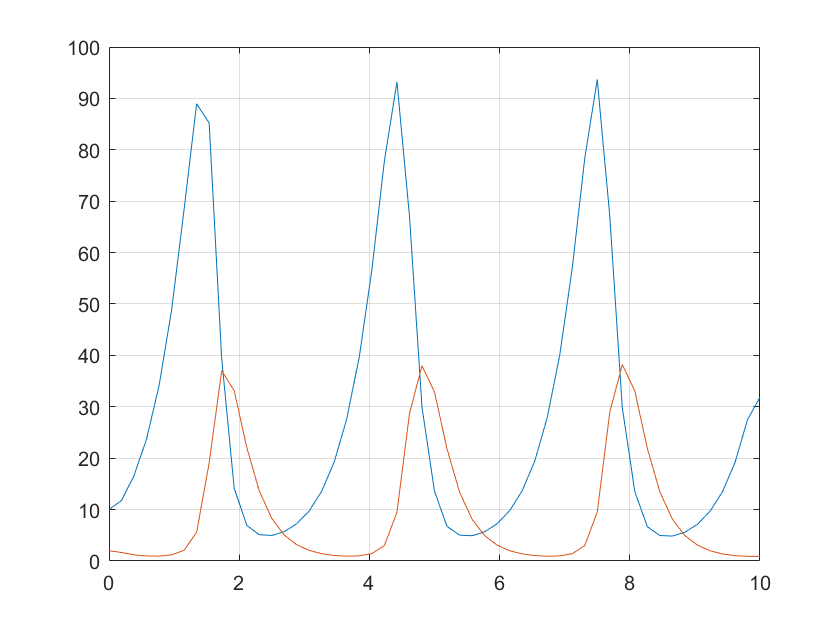

%{
clc
clear all

a = [1.033  2.221  4.321];
fprintf('%1.2f\n', a)

fprintf('%d + %d = %d\n, ', [1, 2, 3])

fprintf('Hello Emilia!')

a = 5^3;
b = factorial(6);
c = exp(2)/3;

fprintf('5^3 = %d\n', a)
fprintf('6! = %d\n', b)
fprintf('(e^2)/3 = %.2f\n', c)

x = 2500;
y = 5 - 12*(exp(-x)/(log(x/2)*sin(2*x)^2));
fprintf('%.3f', nthroot(y, 4))

%MatrixLaboratory

x = [2 5 -3]'
t = 0:.1:2;
t = linspace(0, 2, 21);

x = [0:(pi/4):(4*pi)];
y = cos(x) % katso indeksi 5 (alkaa indeksistä 5)

v = [2:2:1000]';

w = [0.1:0.1:2.0]';

disp(exp(1i*w))

%A = [a, b; c, d]

A = [1, 2, 3; 4, 5, 6; 7, 8, 9];
b = sum(diag(A)) %diagonaalilla olevat arvot vektorina ja sum() laskee summan vektorin elementeistä

A = [1, 2, 3; 4, 5, 6];
% rivit x sarakkeet eli 2 x 3

A = [1, 2, 3; 4, 5, 6; 7, 8, 9];
B = [1, 1, 2; 4, 6, 7; 2, 2, 3];

A*B
A+B
A/B

A = [1 2 3 4 5; 2 3 4 5 6; 3 4 5 6 7; 4 5 6 7 8; 5 6 7 8 9];
A = [1 1 3 4 5; 2 1 4 5 6; 3 1 5 6 7; 4 1 6 7 8; 5 1 7 8 9];

A = 2;
w = 3;
phi = 0.01;
T = 0.02;
n = 100;

tf = (n-1)*T;
t = 0:T:tf;
y = A*sin(w*t + phi);
stem(t,y)
xlabel('$t$','FontSize',20,'Interpreter',"latex")
ylabel('$y$','FontSize',20,'Interpreter',"latex")  

A = [2  0  1 ; 2  0  3; 1  1  -1];
b = [5  1  2]';

syms x y z;

function X = create_X(n, x)
    base = ones(n);
    X = base - eye(n);
    X = x*X;
end



function sqr = sqr(x)
    sqr = x^2;
end

%if ehto_0
%  disp(eye(3))
%elseif ehto_1
%  disp(eye(2))
%else
%  disp("Incorrect input")
%end
%asd

%}


clc 
clear all


%v = []
%i = 0;
%prompt = "Tell me the answer bro.";    
%luku = input(prompt)
%if luku ~(-1)
%    v[i] = luku;
%end
%while luku ~(-1)
%    luku = input(prompt)
%    if luku ~(-1)
%        v[i] = luku;
%    disp(v)

%if jepp ~(-1)
%        v(i) = numero;
%        i = i+1;
%    end

% v = [];
%numero = "What number would you like to set, bro?";
%numero = "";
%x = input(numero)
%i = 1;
%while x ~= -1
%    v(i) = x;
%    %disp(v(i))
%    i = i+1;
%    x = input(numero)
%end
    
    
%help magic

%ans = 0.1*(5/(0.1+10))

% kirjoita koodisi tähän. Alla on esitetty muoto, jossa arvioiva testi kutsuu funktiotasi.

%{

% Testin parametrit ja mittaustulokset
R = 50; % Ohmia; vakio.
I_1 = 2; % Ampeeria; tasavirta.
I = [2*sin(5*linspace(-pi,pi,1000))]; % Ampeeria, 'vaihtovirta'.

% Laske U_1 ja U.
U = R*I
U_1 = R*I_1


function [V1,V2] = seriesVoltages(R1,R2,V)
    V1 = R1.*(V./(R1+R2));
    V2 = R2.*(V./(R1+R2));
end
    
    
% testit kutsuvat funktiotasi tässä muodossa:
% [V1, V2] = seriesVoltages(R1,R2,V)

% numeerinen esimerkki, joka pyörittää sinun koodisi, jos painat 'Run':
[v1, v2] = seriesVoltages(0.1,10,5)
% voit kirjoittaa tähän myös omia testejäsi.


% Kirjoita vastauksesi tähän.

A = [1 3 2; 4 5 6; 7 8 9]
b = [10 11 12]';

X = A*b


function x = karteesinen_tulo(a,b)
    [A,B] = meshgrid(a,b);
    x = [A(:) B(:)];
end

%}

%a = 5*5

%{
f = @(x) 2*x.^2 - 5*x + 8;
x = linspace(-5,5);
y = f(x);

h1 = plot( [0:10], [0:10] );
fig1 = figure(1);
title("Toisen asteen polynomin f(x) kuvaaja välillä [-2, 2]")
xlabel("x"), ylabel("f(x)")
grid on
"\mu_{x1}"
%}

%h1 = plot( linspace(0,10,20), linspace(10,-10, 20) );

%subplot(2,1,1)
% piirrä jotakin ensimmäiseen kuvaan
%subplot(2,1,2)
% piirrä jotakin toiseen kuvaan

%huom: legend, xlim, ylim, zlim, subplot

%{
x = linspace(-1, 3, 150);
f = @(a, b) exp(a*b);
fig = figure(1); j = 1;
for i=-2:3
    subplot(2,3,j)
    plot(x,f(x,i))
    title(['Funktio f_b(x) arvolla b = ', num2str(i)]), grid on
    xlabel("x"), ylabel("f_b(x)")
    j = j + 1;
end
%}

%plot3, meshgrid, surf, surfl, mesh

%{
clc, clear
% määritellään pohjavektorit
x1 = linspace(-2, 8, 150);
x2 = linspace(-2, 8, 150);
z = @(a,b) sin(a.*b) + a + b;
% piirretään viivakuva
fig2 = figure(2);
h1 = plot3(x1,x2,z(x1,x2));
xlabel("x1"), ylabel("x2"), zlabel("z(x1,x2)")
title("plot3 vektoreilla"), grid on
% piirretään meshgridillä pintakuva samasta
fig3 = figure(3);
[X1,X2] = meshgrid(x1,x2);
h2 = plot3(X1,X2,z(X1,X2));
xlabel("x1"), ylabel("x2"), zlabel("z(x1,x2)")
title("plot3 meshgridillä"), grid on


% määritellään pohjavektorit
x1 = linspace(-10, 10, 200);
x2 = linspace(-10, 10, 200);
z = @(a,b) 4*sin(a)+ 6*sin(b) + a + b;
% piirretään 3d-pinta
fig2 = figure(2);
[X1,X2] = meshgrid(x1,x2);
h2 = surf(X1,X2,z(X1,X2));
xlabel("x_1"), ylabel("x_2"), zlabel("z(x_1,x_2)")
title("Funktio z(x_1,x_2) välillä x_1, x_2 \in [-10, 10]"), grid on
h2.LineStyle = ':';

% HUOM: globaali maksimi ja funktion lokaalisti suurin arvo eri asia, joten
esimerkissämme ei voida määrittää globaalia maksimia, koska funktio kasvaa
rajatta.

%}

%plot(x,y, 'ko:') 
%... missä muotoilumääreinä on merkkijono 'ko:', missä k = musta väri, o = ympyrämerkit, : = jono pisteitä. 

%LineWidth

%plot(x,y, 'ko:', 'LineWidth', 1.5)
% sanan jälkeinen parametri on sen pari ja tässä tapauksessa
% skalaarikerroin eli kuvaajasta halutaan 50% paksumpi

%Cell Array

%{
% Mitä tapahtuu kahden vektorin sisällölle?
x1_v = [1, 2, "3", 4, '5']
x2_v = [int8(1), 2, 3, 4, 5.1]
% Tapahtuuko sama soluvektorille?
x1_c = {1, 2, "3", 4, '5'}
x2_c = {int8(1), 2, 3, 4, 5.1}
%}

% (a) lista ilmaisee kaikki alkiot epätarkimmalla datatyypillä
% (b) solulista puolestaan ilmaisee jokaisen alkion omalla datatyypillään
% (jatkoa) vektoria luodessa alkioiden dimensioiden tulee sopia yhteen // solun
% sisällä matriisit voivat olla eri kokoa

%string_v = ["ELEC", "-", "Yhteistyö"]
%char_v = ['ELEC', '-', 'Yhteistyö']

%cell2mat -> solurakenteesta takaisin listaksi

%cell -> tyhjä solurakenne

% muista aaltosulut solurakenteiden yhteydessä x1{4}


%disp(x2_v(1))
%disp(x1_c(5))

%disp(length(string_v) - length(char_v))
% lasku siis 3 - 14 = -11

% complex
% j = i = sqrt(-1)
% exp

% f(t) -> esimerkin tapauksessa arvojen summa on 0
% ympyrä on tasaisesti origon ympärillä ja summaksi tulee 0

% vektoreiden hyödyntäminen monessa tilanteessa

% tic, toc (suoritusnopeuden numeerinen mittaaminen)

%{
Fig = figure(1);
hold on
% Kirjoita ohjelmasi tähän
syms x;
f = @(x) sin(x)*2*x;
g = @(x) cos(x)+x*exp(2);
h = @(x) 4*x^(2)-2*x-log(5*x);
fplot(f, [0 5])
%hold on 
fplot(g, [0 5])
%hold on
fplot(h, [0 5])
hold off
%}

%{
% kuvaaja tallennetaan muuttujaan (eli kahvaan, lisää 4. viikolla) tällä notaatiolla:
% *muuttujan nimi* = *piirtokomento*(*parametrit*);
hold on
% totetuta kuvaajat alla oleviin muuttujiin.

p1 = fplot(@(t) 5*exp(-t)*sin(5*t), [0 8], '--r');

p2 = fplot(@(t) sin(t)-cos(3*t), [0 8], ':b');

hold off
%}

%{
Fig = figure(1); % piirrä tähän kuvaikkunaan.

% sinun koodisi tähän!
x = linspace(0,20);
y = linspace(0,20);
f = @(x,y) cos(x) + exp(2*sin(y));
[X,Y] = meshgrid(x,y);
kuvaaja = surf(X,Y, f(X,Y));
%}

%{
%YRITYS 1

Fig = figure(1); % piirrä tähän ikkunaan
hold on

% Oletuksia:
h_heittohetki = 1.5;
g = 9.81;
v_pallo = 4;
theta_kulma = 45;

t = linspace(0,1,1000);

x = v_pallo.*cos(theta_kulma.*pi/180).*t;
y = h_heittohetki + v_pallo.*sin(theta_kulma.*pi/180).*t-(1/2).*g.*t.^2;

indeksi = find(y<0, 1);

%dist = v_pallo.*cos(theta_kulma.*pi/180).*indeksi;
dist = indeksi;

fplot(x);
fplot(y);
pete = 0;
fplot(pete, '--');
%}

%{
%YRITYS 2
Fig = figure(1); % piirrä tähän ikkunaan
hold on

% Oletuksia:
h_heittohetki = 1.5;
g = 9.81;
v_pallo = 4;
theta_kulma = 45;

t = linspace(0,1,1000); %OIKEIN

x = v_pallo*cos(theta_kulma*pi/180).*t;
y = h_heittohetki + v_pallo*sin(theta_kulma*pi/180).*t - (1/2)*g.*(t.^2);

indeksi = find(y < 0, 1); %Saadaan vastaus 913.

dist = v_pallo*cos(theta_kulma*pi/180)*(indeksi/1000); %Tarvitseeko olla jaettuna 1000:lla? %Onko ylipäätään oikein?
%Toisaalta olisi loogista, jos halutaan aikayksikkö sekunteina, että jaetaan indeksi aikavektorin pisteiden lukumäärällä.
%Näin saadaan luultavasti vastaus sekunteina (913/1000 s).


plot(x, y)
pete = 0; %OIKEIN
fplot(pete, '--'); %OIKEIN
hold off
%}

%                  V I I K K O   4

% etsintäpolku eli search path
% nykyinen kansio eli current directory/folder

%writematrix()
%cd 'C:\path\to\working\directory'
%example_matrix = [1,4,2;5,1,3;3,9,1];
%writematrix(example_matrix)
%type 'example_matrix.txt'


%a = 5*5*5/3


%writematrix(example_matrix, 'example_matrix_tab.txt','Delimiter', 'tab')
%type 'example_matrix_tab.txt'

%writetable, writecell, writetimetable -> HUOM: datarakenteen tyyppi

% .csv -> comma separated values

%cd 'C:\path\to\working\directory' % korjaa osoite jos käytät tätä
example_matrix = [1,4,2;5,1,3;3,9,1];
%writematrix(example_matrix) %EI TUNNISTANUT? (V: johtuu versiosta 2018)
%type 'example_matrix.txt'

% tulostus: riveittäin 1,4,2  (\n)  5,1,3  (\n)  3,9,1  (\n)
% writematrixin tulos on csv-muotoinen!!! (vaikka .txt)

%writematrix(example_matrix, 'example_matrix_tab.txt','Delimiter', 'tab')
%type 'example_matrix_tab.txt'

% tulostus: riveittäin   1  4  2  (\n)  5  1  3  (\n)  3  9  1  (\n)
% Sarake-erotin (Delimiter) on vaihdettu edelliseen verrattuna.


% numeerisen datan tuominen (manuaalisia käyttöliittymätyökaluja ja
% ohjelmallinen tapa)

% csvread + xlsread + ... = readtable (uusissa versioissa)

%X = readtable('filename.txt'); (filename.txt -tiedosto pitää olla etsintäpolulla)

% dokumentaatio -> Input Arguments -> file in a folder
% (tiedoston löytäminen myös polun ulkopuolelta)

% readmatrix, readcell, readtimetable, readvars
% käyttäytyminen sama kuin readtable mutta luovat eril. objektin
% ja soveltuvat eril. käyttötarkoituksiin

% letsgou 17.5.2022 wörkkiä Haraldissa

% kahva/käsittelijä -> osoitin funktioiden jne. muistipaikkoihin
% vertauskuvallisesti kahvasta pidettäessä laukun sisällöt pysyvät mukana
% kahvojen talteen ottaminen -> debuggaamisen helpottaminen, onnistuiko
% ...toimenpide?
% kahvan rooli "käyttöliittymänä" monimutkaisemman rakenteen
% ...manipuloinnissa


%{
%% graphics-object - esimerkki 1: properties of a plot object
clc, clear
% Otetaan talteen kahvat
fig1 = figure(1); % kuvaikkuna
plot1 = plot(1:10); % kuvaaja
ax1 = fig1.Children; % akselisto (huomaa "dot notation"!)
% tulostetaan täysi lista jokaisen attribuuteista.
disp("fig1 properties: "), get(fig1)
disp("ax1 properties: "), get(ax1)
disp("plot1 properties: "), get(plot1)
%}

% sama kahva: plot1.Parent / gca (= get current axis) / fig1.Children

% samantyyppinen esimerkki: gcf (= get current figure)

% HUOM: objektilla voi olla monta lasta mutta vain YKSI vanhempi

% get-funktio -> tulostaa listan KAIKISTA objektin attribuuteista
% kertovat esim. ulkonäöstä
% voi kommentoida pois halutessaan

% HUOM HUOM HUOM: älä sulje figure-ikkunaa!
% kun ikkuna suljetaan, MATLAB poistaa grafiikkaobjektin ja
% ...joudutaan aloittamaan alusta

% KAHVOJA: plot1, ax1, fig1 (tallennettuna työtilaan)

%{

%% Piirretään (major) grid ilman grid-komentoa:
ax1.YGrid = 'on'; ax1.XGrid = 'on';

%% muutetaan kuvaajan piirtotyyliä:
plot1.LineStyle = ':'; plot1.Marker = 'x'; plot1.Color = 'black';

%% poistetaan datapisteitä (aiheuttaa epäjatkuvuuden)
plot1.XData(5:6) = NaN;
%% pistetään takaisin, korjaa epäjatkuvuuuden
plot1.XData(5:6) = [5:6];

%% voidaan myös manipuloida kuvaikkunaa
fig1.Color = 'white'; fig1.Name = "Esimerkki-ikkuna";

% ruudukon piirtäminen
    % haluaa merkkijonon, palauttaa virheen ilman lainausmerkkejä

% datapisteiden manipuloiminen:
    % kohinan poistaminen
    % virhelukemien siistiminen
    % datapisteiden harventaminen
    
% datapiste olemassa, mutta arvo NaN joten se ei piirry
% aiheuttaa epäjatkuvuuden

% tehtävä 5
    % 'replace' -> ax1.NextPlot
    % 0.5000 -> plot1.LineWidth
    % [1x1 Axes] -> plot1.Parent
    % 'line' -> fig1.Children.Children.Type
    % [0.9400 0.9400 0.9400] -> fig1.Color

%}

% tehtävä 6
    % funktiollinen ohjelmointi -> ohjelmoijan sktrukturoimistapa
    % toimintojen erittely ja toteutus erillisissä funktioissa
    % pääohjelma -> sarja funktiokutsuja ja todnäk myös kontrollirakenteita
    
    % jos haluaa: piirtää kuvaajasetti skriptin eri
    % ...välivaiheista/tuloksista
    % (1) sisällytä samat komennot skriptiin (aina kuvaajasettiä
    % ...piirrettäessä)
    % (2) määrittele lokaali funktio (argumenttina data) -> piirtää
    % ...kuvaajan (kutsu tarvittaessa)
    
    % funktioiden ja matriisioperaatioiden hyödyntäminen koodissa
    
    %{
    myave = @(x) sum(x(:)) / numel(x); %OIKEIN!
    %}
    
% doc ja help
% Simulink -> dynaamisten systeemien simulointi
% ...palikkadiagrammi-käyttöliittymällä
    % esimerkki: piirin toiminta ajasta riippuvalla signaalilla
    % esimerkki: nestesäiliön toiminnan simulointi, eri parametrien
    % ...kokeilu, tavoitteena esim. tasainen ulosvirtaus riippumatta
    % ...lyhyistä häiriöstä sisäänvirtauksessa; vain vedenpintaa voidaan
    % ...mitata
    
% Simulinkistä kevyt täydentämistehtävä

%{
file = fopen('TopSecret.txt', 'w');
teksti = "Kurssitentin ensimmäinen tehtävä on [SENSUROITU].";
fprintf(file, teksti);
fclose(file);
%}

% KIERROS 4: HAPPO-EMÄSTITRAUKSEN EKVIVALENTTIPISTE
%{
Fig = figure(1);
hold all
mytable = readtable('titraus.xlsx', 'Sheet', 'Taul1');
%options = detectImportOptions('titraus.xlsx'); %VÄÄRIN?
%options.VariableNamesLine = 1; %VÄÄRIN?
%mytable = readtable('titraus.xlsx', options, 'ReadVariableNames', true); %VÄÄRIN?
x = mytable.Volume_mL_;
y = mytable.pH;
plot(x,y);
pisteet = 1:length(mytable.pH);
ekvi = find(max(interp1(pisteet, mytable.pH)));
%}

% CLEAN VERSION:
%{
Fig = figure(1);
hold all
mytable = readtable('titraus.xlsx', 'Sheet', 'Taul1');
x = mytable.Volume_mL_;
y = mytable.pH;
plot(x,y);
pisteet = 1:length(mytable.pH);
ekvi = find(max(interp1(pisteet, mytable.pH)));
%}
    
% KIERROS 4: KONDENSAATTORIN TYHJENEMINEN

%{
Fig = figure(1);
hold all
kondis = readtable('kondensaattori.xlsx', 'Sheet', 'Taul1');
aika =  kondis.Aika_s_;
virta = kondis.Virta_A_;
potentiaali = kondis.Potentiaali_V_;
t = linspace(1.8,2.2,((2.2-1.8)/0.001)+1)';
subplot(2,1,1);
plot(aika, virta);
subplot(2,1,2);
plot(aika, potentiaali, 'r');
%}

% KIERROS 5: Soveltaminen

% KIERROS 5: SIGNAALIN LÖYTÄMINEN KOHINASTA
%{
A = randi([1 5]);    % Amplitudi välillä 1.. 5
f = randi([50 79]);  % Taajuus välillä 50.. 79 Hz
Fs = 500;            % Näyteenottotaajuus (Hz)
dt = 1/Fs;           % Näytteenottoaika
L = 512;             % Datapisteiden lukumäärä
t = (0:L-1)*dt;      % Aikavektori
S = A*cos(2*pi*f*t) + randn(size(t));   % Kohinallinen signaali
% Piirtää signaalin kuvaajan ja näyttää taajuuden ja amplitudin
figure; plot(t,S)
title([num2str(f), ' Hz signal with amplitude = ', num2str(A)])
xlabel('Time (s)')
ylabel('Amplitude (A.U.)')

freq = linspace(0,Fs/2,L/2+1);
Y = fft(S, L);
p2 = abs(Y/L);
p1 = p2(1:L/2+1);
p1(2:end-1) = 2*p1(2:end-1);
f = Fs*(0:(L/2))/L;

plot(f,p1)
[max, index] = max(p1);
%[max, index] = max(fft(S));
%}

%{
freq = linspace(0,Fs/2,L/2+1);

Y = fft(S, L);
Y_abs_per_L = abs(Y/L);
Y_abs_per_L_bounded = Y_abs_per_L(1:L/2+1);
Y_abs_per_L_bounded(2:end-1) = 2*Y_abs_per_L_bounded(2:end-1);
[m, i] = max(Y_abs_per_L_bounded);

f = Fs*(0:(L/2))/L;
plot(f, Y_abs_per_L_bounded);

fftFrequency = i
%}

%fft_max = 0;
%{
for i = 0:Fs/2
    fft(S,i);
    if fft(S,i) > fft_max
        fft_max = i;
    end
end
%}
%fftFrequency = index

%{
Y = fft(S);
p2 = abs(Y/(L+1));
p1 = p2(1:(L+1)/2+1);
p1(2:end-1) = 2*p1(2:end-1);
f = Fs*(0:((L+1)/2))/(L+1);
plot(f,p1)
[max, index] = max(p1);

%[max, index] = max(fft(S));


%fft_max = 0;
%{
for i = 0:Fs/2
    fft(S,i);
    if fft(S,i) > fft_max
        fft_max = i;
    end
end
%}
%[pks,locs,widths,proms] = 
fftFrequency = findpeaks(p1, freq, 'descend',1);

%maksimi = find(max(p1(index)));
%fftFrequency = max(widths)
%}

%{
freq = linspace(0,Fs/2,L/2+1);

Y = fft(S, L);
p2 = abs(Y/L);
[max, index] = max(p2);
fftFrequency = freq(index)
%}

%{
%for i = 1:length(freq)
%    fprintf('%c\n', freq(i));
%end
%}

% YKSI OIKEA RATKAISU
%{
freq = linspace(0,Fs/2,L/2+1);

Y1 = abs(fft(S)/L);
[max, index] = max(Y1);
fftFrequency = freq(index)
%}

% KIERROS 5: 3D - KUVAAJANPIIRTO

%{
fig = figure(1);
hold all

x = linspace(-2,2);
y = linspace(-2,2);
z = @(x,y) -(x.^2+2.*y.^2).*exp(1-x.^2-y.^2);
[X,Y] = meshgrid(-2:0.16:2);
Z = -(X.^2+2.*Y.^2).*exp(1-X.^2-Y.^2);

subplot(3,2,1);
figure(fig);
mesh(X,Y,Z);
title('Mesh');
xlabel('X');
ylabel('Y');
zlabel('Z');
xticks(-2:1:2);
yticks(-2:2:2);
zticks(-2:0.5:0);

subplot(3,2,2);
figure(fig);
surf(X,Y,Z);
title('Surf');
xlabel('X');
ylabel('Y');
zlabel('Z');
xticks(-2:1:2);
yticks(-2:2:2);
zticks(-2:0.5:0);

subplot(3,2,3);
figure(fig);
plot3(X,Y,Z,'.');
title('Plot3');
xlabel('X');
ylabel('Y');
zlabel('Z');
xticks(-2:1:2);
yticks(-2:2:2);
zticks(-2:0.5:0);

subplot(3,2,4);
figure(fig);
contour(X,Y,Z,20);
title('Contour');
xlabel('X');
ylabel('Y');
xticks(-2:1:2);
yticks(-2:0.5:2);
a = colorbar('Xtick', [-1.8:0.2:-0.2]);

subplot(3,2,5);
figure(fig);
kuva_surfl = surfl(X,Y,Z);
kuva_surfl.EdgeColor = 'none';
title('Surfl');
xlabel('X');
ylabel('Y');
zlabel('Z');
xticks(-2:2:2);
yticks(-2:2:2);
zticks(-2:0.5:0);
colorbar('Xtick', [0:0.2:1]);

subplot(3,2,6);
figure(fig);
pcolor(X,Y,Z);
title('Pcolor');
xlabel('X');
ylabel('Y');
xticks(-2:1:2);
yticks(-2:0.5:2);
colorbar('Xtick', [-2:0.5:0]);
%}


% KIERROS 5: KUVAAJIEN KÄSITTELIJÄT

% Kirjoita vastauksesi tähän

%{
for i = 1:length(h.XData)
    if h.YData(i) >= 11
        plot(h.XData(i),h.YData(i), 'o');
        % VÄÄRIN %h.XData(i) = (1/2)*(h.YData(i-1)+h.YData(i+1));
        % VÄÄRIN %h.YData(i) = (1/2)*(h.YData(i-1)+h.YData(i+1));
        h.XData(i) = NaN;
        h.YData(i) = NaN;
    end
end

hold off
%}


% KIERROS 5: SATUNNAISARVONTA JA KUVAILEVA STATISTIIKKA

%rng('default') % asetetaan ja alustetaan tietty (oletus) arvontamenetelmä ja siemen (eng. seed) jotta tulokset samat
% tee arvonta vain kolme kertaa, kerran per jakauma, järjestyksessä normaali - tasa - khii^2. Näin saat tulokset mitä tarkistin käyttää!

%{
% Normaalijakauma, 5000~N(12,2)
standard_deviation = 2;
mean_1 = 12;
N = standard_deviation.*randn(1,5000) + mean_1;

% Tasajakauma, 5000~[0,24]
alku = 0;
loppu = 24;
U = (loppu-alku).*rand(1,5000) + alku;

% Chi^2 -jakauma, 5000~X^2(5)
df = 5;
X = chi2rnd(df,1,5000);

% Laske näytteiden keskiarvo, mediaani ja keskihajonta; tallenna ne matriisiin DESC annetun ohjeen mukaisesti
normal_mean = mean(N); %sum(N)/length(N); %mean(N);
normal_median = median(N);
normal_sd = std(N);
uniform_mean = mean(U); %sum(U)/length(U); %mean(U);
uniform_median = median(U);
uniform_sd = std(U);
chi2_mean = mean(X); %sum(X)/length(X); % mean(X);
chi2_median = median(X);
chi2_sd = std(X);
DESC = [normal_mean, normal_median, normal_sd; uniform_mean, uniform_median, uniform_sd; chi2_mean, chi2_median, chi2_sd];;

% Piirrä kolme kuvaajaa annetun ohjeen mukaisesti:
fig1 = figure(1);
% histogram()-komennolla voi helposti piirtää näytteen histogrammin ilman suurempaa säätöä
% subplot()-komennolla saa aseteltua kuvaajat helposti, kuten ennenkin
% hold on/off - komennolla saa hallittua piirretäänkö kuvaajat edellisten päälle
hold on
subplot(3,1,1);
histogram(N);
xline(uniform_mean);
xline(uniform_median);
xline(uniform_mean+uniform_sd);
xline(uniform_mean-uniform_sd);
title('Normal, N(12/2)');

subplot(3,1,2);
histogram(U);
xline(normal_mean);
xline(normal_median);
xline(normal_mean+normal_sd);
xline(normal_mean-normal_sd);
title('Uniform, [0,24]');

subplot(3,1,3);
histogram(X);
xline(chi2_mean);
xline(chi2_median);
xline(chi2_mean+chi2_sd);
xline(chi2_mean-chi2_sd);
title('\chi^2, df=5');
%}

% KIERROS 6 / SIMULINK:

% Mikä se on?
    % (1) dynaamisten systeemien mallintamiseen ja simuloimiseen tarkoitettu
    %...ohjelmointiympäristö
    % (2) palikoiden yhdistelyä
    % (3) C-koodina ulos vieminen
    % (4) käytössä säätötekniikassa (piirit)
    
% Kolmenlaisia palikoita
    % (1) lähteet
    % (2) toimenpiteet
    % (3) lähdöt
    
% Dynaamisuus
    % (=) eli systeemillä 'muistia' tai sen tila riippuu historiasta

% SIMULINK-TUTORIAALI:

% (1) Simulinkin käynnistäminen
    % Matlab-komento TAI klikkaamalla käyttöliittymästä
    % Blank model
% (2) Mallin luominen
    % Library Browser TAI tuplaklikkaus hakuun
    % nuolinäppäin + Enter
    % nimet -> kursori -> ... -> Show Block Name
% (3) Simuloiminen
    % Run
    % tuplaklikkaa Scope-lohkoja
% (4) Matlabiin kytkeminen ja skriptissä käyttö
    % poista scope-lähtö ja scope-ulostulon tilalle "To Workspace"
    % parametri: Timeseries tilalle Array
    % Sine Wave -> Amplitude = A & Frequency = f
    % Gain: Gain = a
% (5)
    %{
    %% Malli 1: vakiovahvistettu signaali
    % yksinkertainen demonstraatio matlab-kytkennästä.
    % Simulink-mallin nimi: simulink_intro.slx
    clc, clear

    a = 2; % Gain-parametrit
    A = 1; f = 1; % Sine Wave - parametrit

    out = sim('simulink_intro');
    t = linspace(0,10,length(out.signal));

    plot(t, out.signal), grid on
    hold on
    plot(t, sin(t))
    hold off
    %}
% (6)
    % tallenna skripti ja simulink-malli samaan kansioon
    % aseta Working Directory tähän kansioon
    % muista Simulink-mallin tiedostonimi
    % out-muuttuja -> sim-komennon paluuarvot
    

% SIMULINK - TEHTÄVÄ, OSA 1

%{
clc, clear

a = 2; b = 0.2; d = 0.1; g = 3;
x(1) = 10; y(1) = 2; % indeksin 0 tilalla 1
x_deriv = @(x,y) a*x(t)-b*x(t)*y(t);
y_deriv = @(x,y) d*x(t)*y(t)-g*y(t);
t = 4.4942;

out = sim('Simulink_t1');
t_x = linspace(0,10,length(simout_x));
t_y = linspace(0,10,length(simout_y));

plot(t_x, simout_x), grid on
hold on
plot(t_y, simout_y)
hold off


%tmp = 1:numel(ts.t_x);
%m = linspace(numel(simout_x));
%a = find(, t_x == 4.492)
%numel(simout_y)

for i = 1:53
    fprintf("%f\n", simout_x(i))
end

10.000000
11.787364
16.625978
23.760130
34.122289
48.824714
68.458605
88.967722
85.214856
39.425512
14.167500
6.948969
5.121503
4.970077
5.711318
7.255874
9.775394
13.623984
19.351473
27.744451
39.838850
56.697277
77.887827
93.212236
67.144733
29.934894
13.572501
6.741516
5.027461
4.918105
5.680764
7.240685
9.775496
13.643291
19.398186
27.832802
39.992495
56.954425
78.298417
93.708939
67.090131
29.836995
13.515472
6.672543
4.962709
4.849539
5.599886
7.138105
9.639415
13.458055
19.143039
27.481761
31.886294


  
for i = 1:53
    fprintf("%f\n", t_x)
end

0.000000
0.192308
0.384615
0.576923
0.769231
0.961538
1.153846
1.346154
1.538462
1.730769
1.923077
2.115385
2.307692
2.500000
2.692308
2.884615
3.076923
3.269231
3.461538
3.653846
3.846154
4.038462
4.230769
4.423077
4.615385
4.807692
5.000000
5.192308
5.384615
5.576923
5.769231
5.961538
6.153846
6.346154
6.538462
6.730769
6.923077
7.115385
7.307692
7.500000
7.692308
7.884615
8.076923
8.269231
8.461538
8.653846
8.846154
9.038462
9.230769
9.423077
9.615385
9.807692
10.000000
0.000000
0.192308
0.384615
0.576923
0.769231
0.961538
1.153846
1.346154
1.538462
1.730769
1.923077
2.115385
2.307692
2.500000
2.692308
2.884615
3.076923
3.269231
3.461538
3.653846
3.846154
4.038462
4.230769
4.423077
4.615385
4.807692
5.000000
5.192308
5.384615
5.576923
5.769231
5.961538
6.153846
6.346154
6.538462
6.730769
6.923077
7.115385
7.307692
7.500000
7.692308
7.884615
8.076923
8.269231
8.461538
8.653846
8.846154
9.038462
9.230769
9.423077
9.615385
9.807692
10.000000
0.000000
0.192308
0.384615
0.576923
0.769231


t_x(24)

ans = 4.4231

simout_x(24)

ans = 93.2122

simout_y(24)

ans = 9.4829

fprintf("\n");

t_x(41)

ans = 7.6923

simout_x(41)

ans = 67.0901

simout_y(41)

ans = 28.9237

%}


% SIMULINK - TEHTÄVÄ, OSA 2

%{
% piirrä kuvaajat tähän ikkunaan.
fig1 = figure(1);
filename = "simulink_esim_malli_data"
load(filename);
% tallenna data näihin muuttujiin, voit pretestillä varmistaa että ne ovat oikein.
t = out.tout;
X = out.x_out;
Y = out.y_out;
subplot(1,2,1);
plot(t,X);
grid on
hold on
plot(t,Y);
title("Populaatio-aika kuvaaja");
xlabel("Aika");
ylabel("Populaatio");
legend("Jänikset", "Ketut");
subplot(1,2,2);
plot(X,Y,':xr');
grid on
title("Vaihekaavio");
xlabel("Jänisten määrä");
ylabel("Kettujen määrä");
hold off
%}


% KIERROS 7 / R-KATSAUS (käytetyin data-analyysin työkalu):

% Mikä se on?
    % ilmainen avoimen lähdekoodin ohjelmointikieli ja -ympäristö
    % soveltuu parhaiten:
    % (1) statistiikkaan, (2) mallintamiseen, (3) aikasarja-analyysiin,
    % (4) datan käsittelyyn ja (5) datan visualisoimiseen
    % (extra 6) muuhunkin käyttöön
    % paljon laajennuksia saatavilla -> omistautunut yhteisö
    % yksi käytetyimmistä matemaattisista ohjelmointikielistä! :)
    
% Miten työskennellä R:n kanssa?
    % komentorivikäyttöliittymällä TAI kirjoittamalla koodin
    % ".r"-tiedostoon ja ajamalla komentoriviltä
    % KÄTEVIN TAPA: käyttää kolmannen osapuolen tarjoamaa integroitua
    % kehittely-ympäristöä (IDE)
    
    % RStudio Desktop -> kurssilla käytössä & ilmainen, omistautunut
    % yhteisön kehittämiseen
    
% Millä aloilla R:ää käytetään? Miksi opetella?
    % DATA-ANALYYSI (kerääminen, järjestely, analyysi)
    % (1) finanssiala
    % (2) empiirinen tutkimus
    % (3) kvantitatiivinen tutkimus
    % (4) datalouhinta
    % MATLABIN KORKEA HINTA (kaupallisessä käytössä, lähes 1000e/nenä/v)
    % R:N ILMAISUUS (houkuttelee yrityksiä)

% käyttöliittymä miltei samanlainen kuin Matlabissa    
    
    % HUOMIO: R-KIELTÄ!

%{
    ?komento
    ??termi
    help(package = 'laajennuksen nimi')
%}
    
%  > viesti <- "Hello world!"
%  > print(viesti)
%  [1] "Hello world!"

% TEHTÄVÄ 1: MITÄ KOODI TULOSTAA? PÄÄTTELE. TARVITTAESSA AJA R-KOODI.

%{
j <- 10
for (i in 3:8) {
  if (2*i < 10) {
    print(2*i)
  } else {
    print(i)
  }
  j <- j + i
}
print(j)
%}

%{
j = 10+3+4+5+6+7+8
printtaa:
6
7
5
6
7
8
43
%}

% TEHTÄVÄ 2: YHDISTÄ KOMENTO/FUNKTIO/OPERAATTORI JA SEN TEKEMÄ OPERAATIO

%{
summary(data) -> esittelee dataa lyhyesti
x[ x >= 0 ] -> palauttaa kaikki vektorin arvot, jotka ovat epänegatiivisia
A != B -> Onko A erisuuri kuin B?
rep(1:3, each=3) -> palauttaa vektorin [ 1 1 1 2 2 2 3 3 3 ]
data( iris ) -> lataa nimetyn datasetin ympäristöön
rep(1:3, times=3) -> palauttaa vektorin [ 1 2 3 1 2 3 1 2 3 ]
%}

% TEHTÄVÄ 3: YHDISTÄ OPERAATIO/FUNKTIO/KOMENTO JA SEN SUORITTAMA OPERAATIO

%{
round(x,n) -> pyöristää parametrin x arvon n:teen desimaaliin
getwd() -> etsii ja palauttaa "nykyisen kansion", mistä etsitään input-tiedostoja ja tallennetaan output-tiedostoja
L <- list( asia1, asia2 ) -> tallentaa listaobjektin muuttujaan L, joka sisältää asioita. Asiat voivat olla eri tietotyyppejä
plot(x,y) -> piirtää kuvaajan x:n ja y:n arvoista
sort(x) -> palauttaa x:n arvot asetettuna kasvavaan järjestykseen
ls() -> listaa kaikki muuttujat editorin ympäristössä/työtilassa
x[ c(2, 6) ] -> palauttaa x:n elementit indekseillä kaksi ja kuusi
df <- data.frame( asia1, asia2 ) -> luo listaobjektin, jonka erikoispiirteenä on kaikkien elementtien yhtäsuuri pituus
rm(A) -> poistaa muuttujan A ympäristöstä/työtilasta
M <- matrix( x, nrow=3, ncol=3 ) -> luo 3x3 -matriisin, jonka sisältö on x-vektorin arvot
%}

% YLEISTÄ INFOA:

    % R:n ja RStudion etu -> mukana tulevat datasetit, joilla voi testata
    % toiminnallisuuksia
    
    % datasetti "iris" -> 150 mittatulost kukan terälehdistä, kolmesta eri
    % lajista -> data on "data frame" -tyyppisessä tietorakenteessa
    % -> käytännössä taulukko nimettyine sarakkeineen
    
    % lataa komennolla: data(iris)
    % funktioita: (1) View(), (2) summary(), (3) head()

%{
% TEHTÄVÄ 4: 

data(iris)
View(iris)
summary(iris) -> nähdään, että Sepal.Length:n sarakkeessa -> Mean: 5.843

% TEHTÄVÄ 5:

setosa <- iris[iris$Species == 'setosa',] -> vain Setosa-lajikkeen kukat tallentuvat iriksen riveistä setosa-nimiseen data frameen
% Setosa-lajikkeen Petal.Width-sarakkeen maksimi?
View(setosa)
summary(setosa) -> Max.: 0.600

% TEHTÄVÄ 6:

versicolor <- iris[iris$Species == 'versicolor',]
View(versicolor)
values <- versicolor[versicolor$Sepal.Width > 3 & versicolor$Sepal.Width < 4,]
% values -> sisältää kahdeksan objektia
%}